## Axially loaded bar: The Finite Element Solution

from IFEM.CH11.pdf, ASEN 5007 Introduction to Finite Element Methods Course Syllabus - Fall 2015 

**Discretization**

The first step in the finite element approach is to divide the domain into **elements** and **nodes**, i.e., to create the **finite element mesh**.

Let us consider a simple situation and divide the rod into 3 elements and 4 nodes as shown in the next figure.

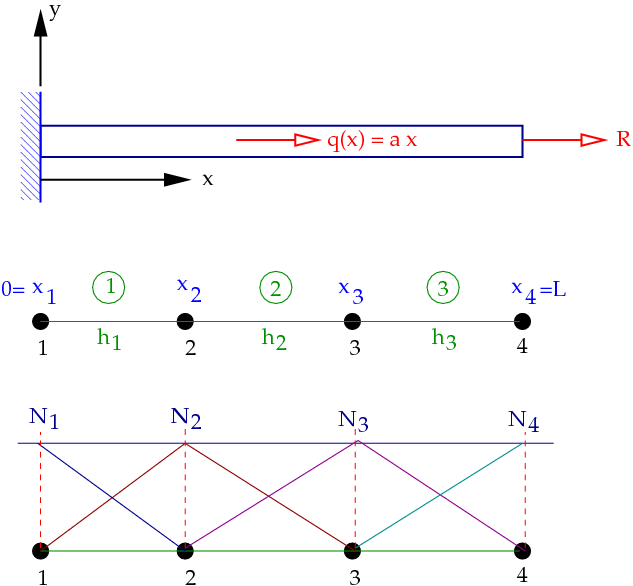

Figure 1. Finite element mesh and basis functions for the bar.			

The mathematical concept of bar finite elements is based on *approximation *of the axial displacement *u*(*x*) over the element. The exact displacement *u*∗ is replaced by an approximate displacement 


$$u^{*}(x)=u^{e}(x)$$


## Shape functions 

The functions $\varphi_i$have special characteristics in finite element methods and are generally written as $N_i$ and are called '''basis functions''', ''' shape functions''', or ''' interpolation functions'''.

In a two-node bar element the only possible variation of the displacement ue that satisfies the interelement continuity requirement stated above is linear. It can be expressed by the interpolation formula $u^{e}$ = $N_1 u_1 +N_2 u_2 = [ N_1\:N_2 ] [u_1\: u_2]^T = N*u^T$ 

 2 special cases on the BCs...

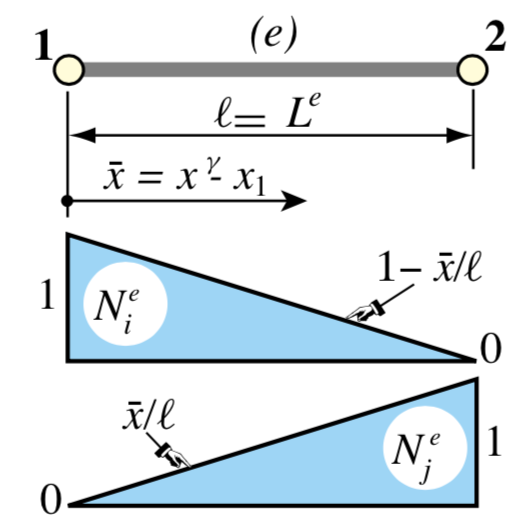

in the element space e we can write (x/l often called zeta)

We replace hand computing with symbolic computing

syms x l real
syms E A real
syms u_1 u_2 real

N_1=1-x/l

$$N\_1 = 1-\frac{x}{l}$$

N_2=x/l

$$N\_2 = \frac{x}{l}$$

N= [ N_1 N_2]

$$N = \left(\begin{array}{cc} 1-\frac{x}{l} & \frac{x}{l} \end{array}\right)$$

U= [u_1 u_2]

$$U = \left(\begin{array}{cc} u_{1} & u_{2} \end{array}\right)$$


ue=N*U'

$$ue = \frac{u_{2}\,x}{l}-u_{1}\,\left(\frac{x}{l}-1\right)$$

## **The Strain-Displacement Equation**

 The axial strain over the element is given by

 
$$\epsilon=\frac{du^{e}}{dx}$$
 
$$= [ \frac{dN_1}{dx}\:\frac{dN_2}{dx}\ ] [u_1\: u_2]^T =\frac{dN}{dx}*u^T = B*u^T $$
 

B=diff(N,x)

$$B = \left(\begin{array}{cc} -\frac{1}{l} & \frac{1}{l} \end{array}\right)$$

%B = [-1/h 1/h]; %with l=h step of discretization

B is called the *strain-displacement *matrix. 	 

epsilon=B*U'

$$epsilon = \frac{u_{2}}{l}-\frac{u_{1}}{l}$$

%

How can I get the stiffness matrix ???

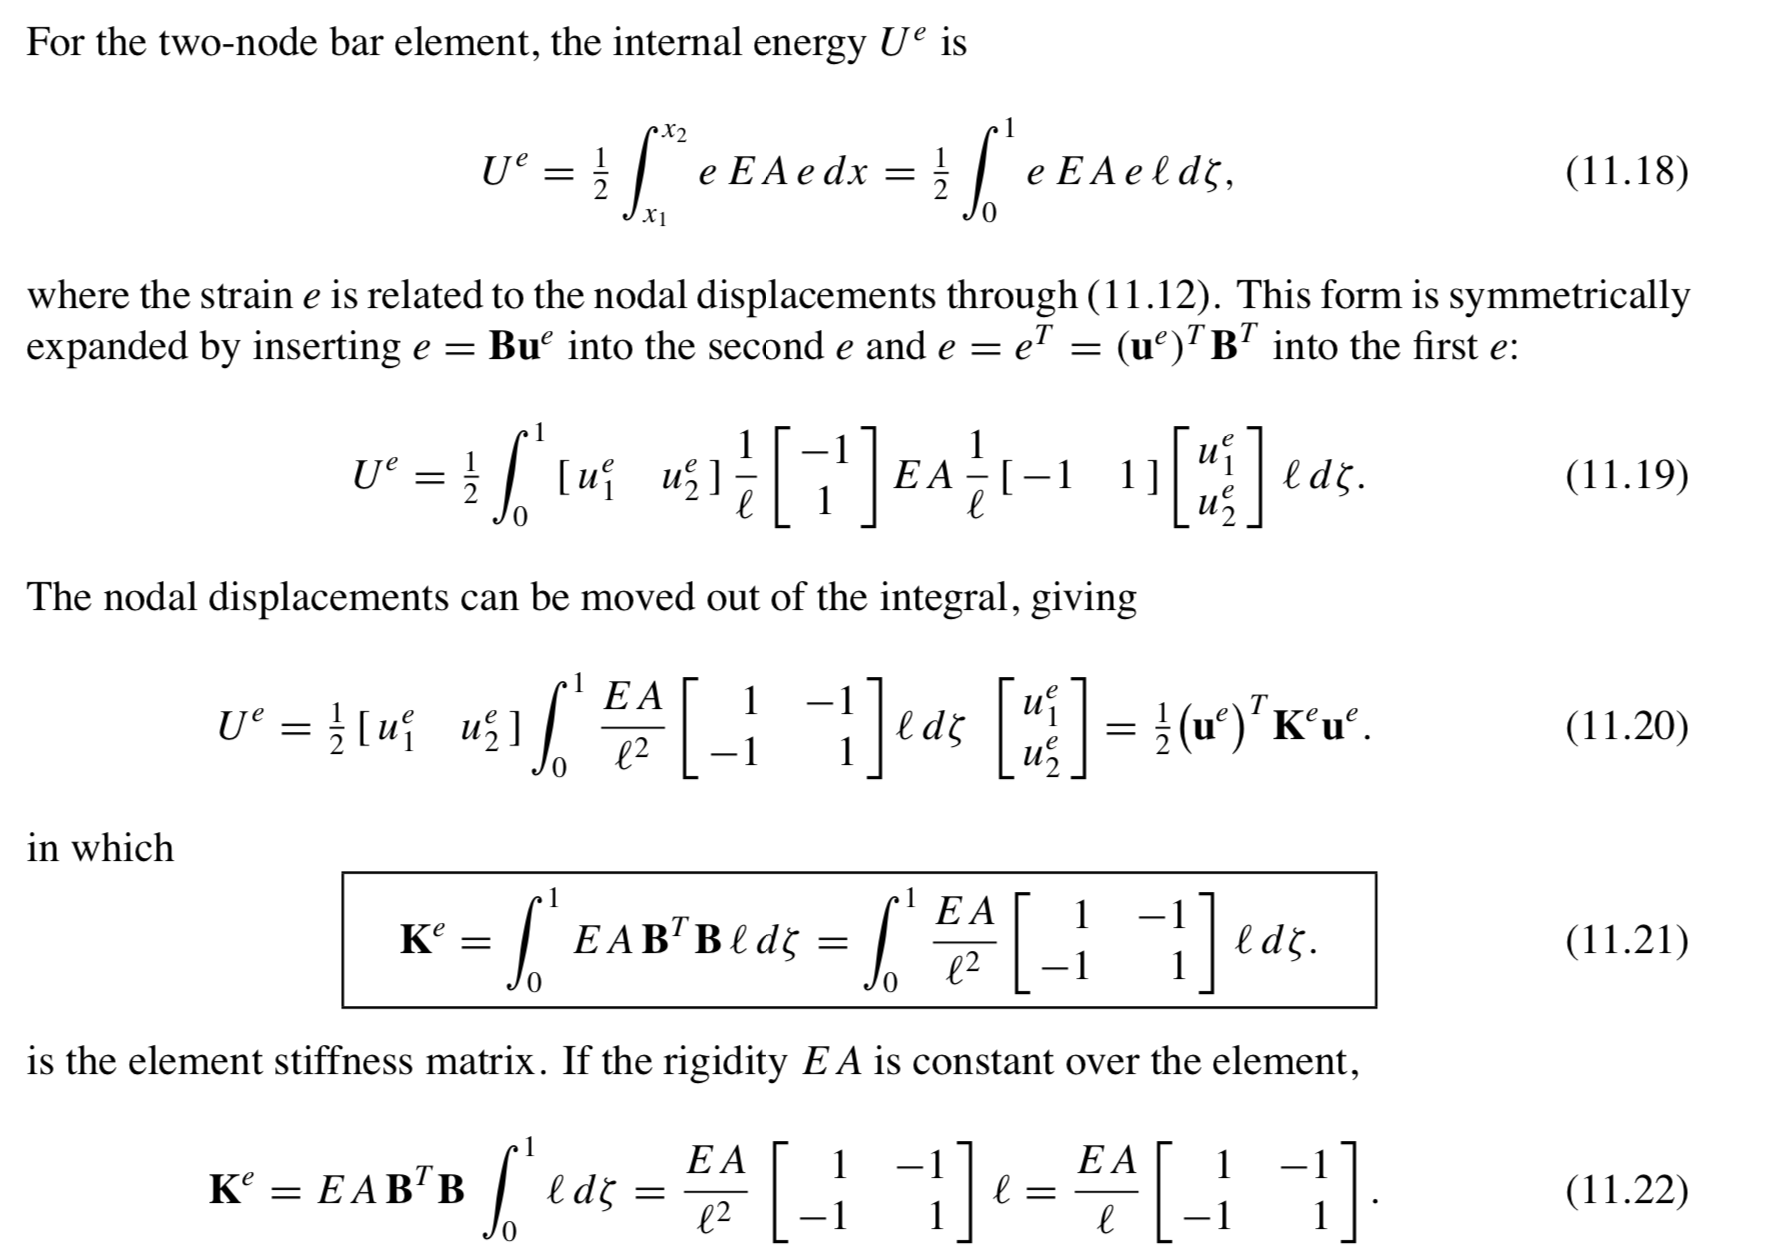

syms zeta real
Ke=E*A*B'*B*int(l,zeta,[0 1])

$$Ke = \left(\begin{array}{cc} \frac{A\,\text{E}}{l} & -\frac{A\,\text{E}}{l}\\ -\frac{A\,\text{E}}{l} & \frac{A\,\text{E}}{l} \end{array}\right)$$

% Ke = (A*E/h)*[[1 -1];[-1 1]];  %with l=h step of discretization

You can see, have to construct Ke ONLY once !

Now it's time for force vector construction

## 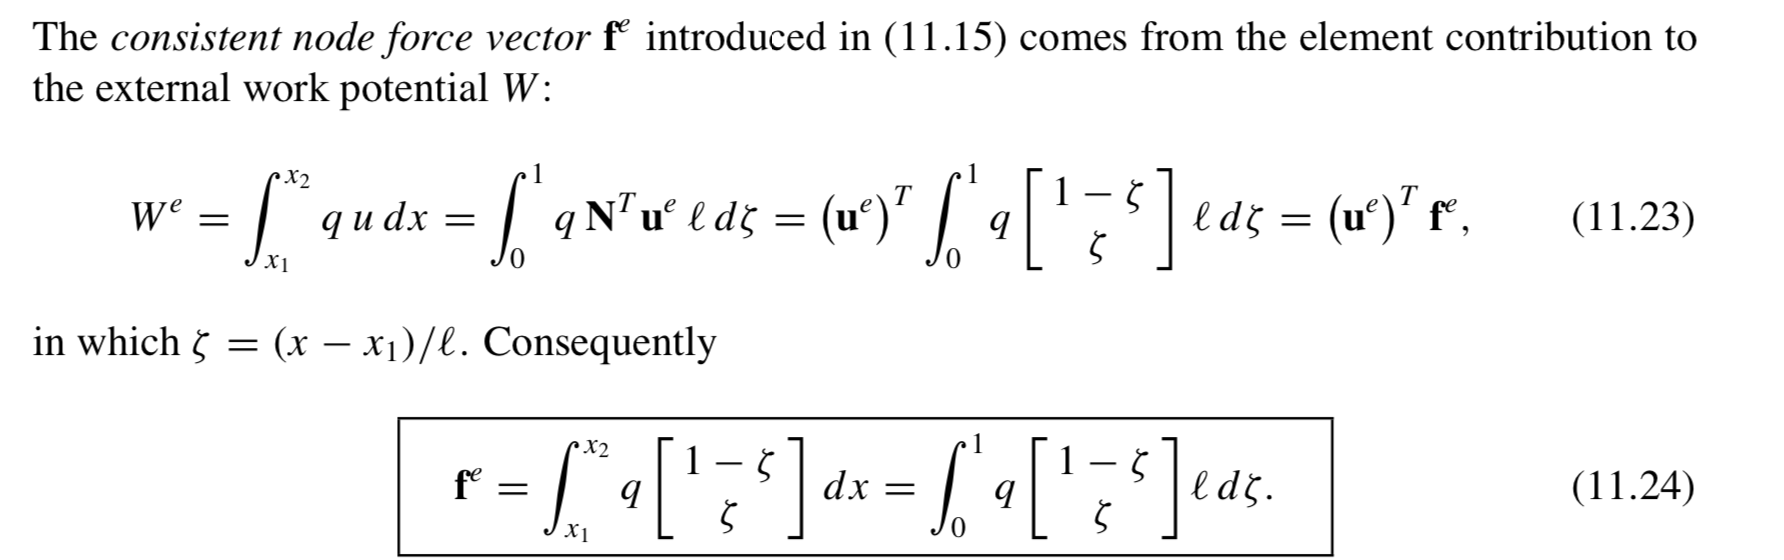

syms q a zeta x_1 x_2 real

Nzeta=[1-zeta zeta]

$$Nzeta = \left(\begin{array}{cc} 1-\zeta & \zeta \end{array}\right)$$

fe=int(q*Nzeta'*l,zeta,[0 1])

$$fe = \left(\begin{array}{c} \frac{l\,q}{2}\\ \frac{l\,q}{2} \end{array}\right)$$

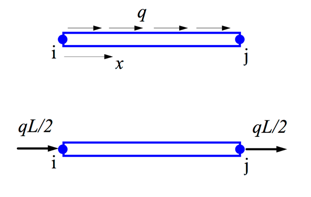that's the check from the course using zeta space

Now apply to our problem, q=ax

for each element

Nzeta=[(x_2-x)/l (x-x_1)/l]

$$Nzeta = \left(\begin{array}{cc} -\frac{x-x_{2}}{l} & \frac{x-x_{1}}{l} \end{array}\right)$$

q=a*x

$$q = a\,x$$

q*Nzeta'% just have a look

$$ans = \left(\begin{array}{c} -\frac{a\,x\,\left(x-x_{2}\right)}{l}\\ \frac{a\,x\,\left(x-x_{1}\right)}{l} \end{array}\right)$$

fe= int(q*Nzeta',x,[x_1 x_2])

$$fe = \left(\begin{array}{c} \frac{a\,{\left(x_{1}-x_{2}\right)}^{2}\,\left(2\,x_{1}+x_{2}\right)}{6\,l}\\ \frac{a\,{\left(x_{1}-x_{2}\right)}^{2}\,\left(x_{1}+2\,x_{2}\right)}{6\,l} \end{array}\right)$$


fe=expand(simplifyFraction(int(q*Nzeta',x,[x_1 x_2])))

$$fe = \left(\begin{array}{c} \frac{a\,{x_{1}}^{3}}{3\,l}+\frac{a\,{x_{2}}^{3}}{6\,l}-\frac{a\,{x_{1}}^{2}\,x_{2}}{2\,l}\\ \frac{a\,{x_{1}}^{3}}{6\,l}+\frac{a\,{x_{2}}^{3}}{3\,l}-\frac{a\,x_{1}\,{x_{2}}^{2}}{2\,l} \end{array}\right)$$

%fe1 = a*x2/(2*h)*(x2^2-x1^2) - a/(3*h)*(x2^3-x1^3);
%with l=h step of discretization

%check
%fe1 = 1/(6*h)*( 3a*x2*(x2^2-x1^2) - 2*a*(x2^3-x1^3) );
%fe1 = 1/(6*h)*( 3a*x2^3 -3*a*x2*x1^2 - 2*a*x2^3 +2*a*x1^3 );
%fe1 = 1/(6*h)*( a*x2^3 -3*a*x2*x1^2 +2*a*x1^3 );


%fe2 = -a*x1/(2*h)*(x2^2-x1^2) + a/(3*h)*(x2^3-x1^3);
%with l=h step of discretization

%check
%fe2 = 1/(6*h)*(-3*a*x1*(x2^2-x1^2) + 2*a*(x2^3-x1^3));
%fe2 = 1/(6*h)*( -3*a*x1*x2^2 +1*a*x1^3 + 2*a*x2^3 );

%construct vector
%  fe = [fe1;fe2];